8)

a)Utiliza un operador basado en un filtro de paso alta para la detección de los contornos de los granos de arroz de la imagen de la figura 26.

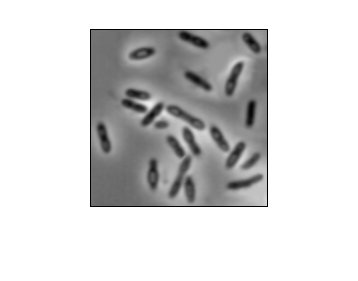

I=imread('bacteria.tif'); 
imshow(I) 

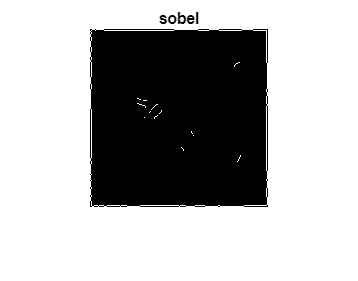

B1=edge(I,'sobel'); 
B2=edge(I,'prewitt'); 
B3=edge(I,'canny'); 
imshow(B1),title('sobel') 

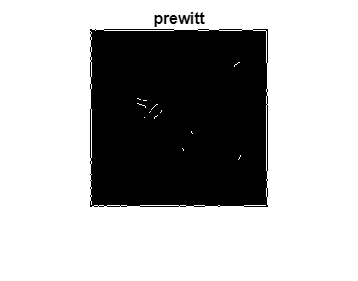

figure,imshow(B2),title('prewitt') 

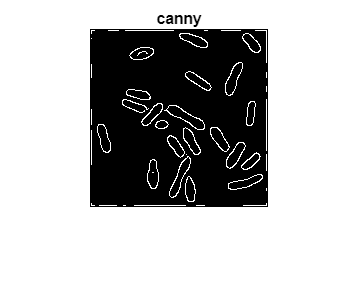

figure, imshow(B3),title('canny') 

b) Detecta los bordes horizontales de la imagen de la figura 26 aplicando un filtro de paso alta. 

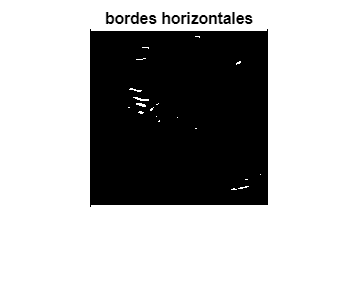

I=imread('bacteria.tif');  
g=[1 1 1;0 0 0; -1 -1 -1]; 
J=filter2(g,I); 
J=abs(J); 
B=J>0.27*(max(J(:))-min(J(:))); 
imshow(B),title('bordes horizontales') 

c) Detecta los bordes verticales de la imagen de la figura 29 (wafer1.tif).

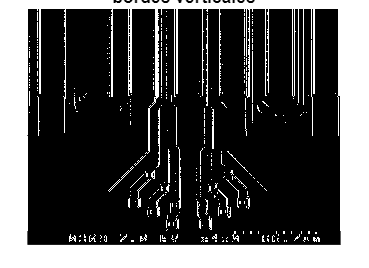

I=imread('WAFER1.TIF');  
g = [1 0 -1; 1 0 -1; 1 0 -1]; 
J=filter2(g,I); 
J=abs(J); 
B=J>0.27*(max(J(:))-min(J(:))); 
imshow(B),title('bordes verticales')

d) Aplica un filtro de pasa alta a la imagen de la figura 31 y muestra la imagen resultante. 

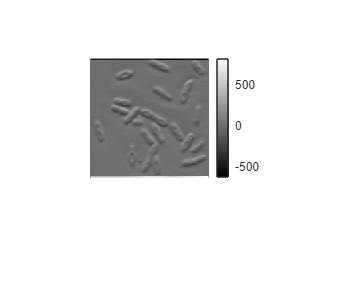

I=imread('bacteria.tif'); 
h=[1 2 1; 0 0 0; -1 -2 -1]; 
I1=filter2(h,I); 
imshow(I1,[]), colorbar 

9)

a) Acentúa (perfila) los contornos a la imagen de la figura 31.

I=imread('bacteria.tif'); 
h=fspecial('unsharp') 

h =    -0.1667   -0.6667   -0.1667
   -0.6667    4.3333   -0.6667
   -0.1667   -0.6667   -0.1667


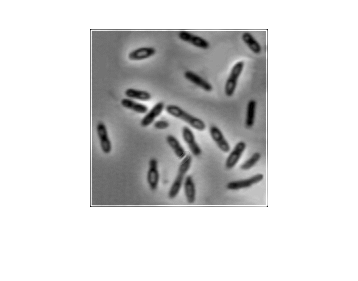

J=abs(filter2(h,I)); 
J1=J/255; % /max(J(:)); 
imshow(J1) 

b) Añade ruido gaussiano a la imagen de la figura 31 y a continuación restaura y realza la imagen resultante.

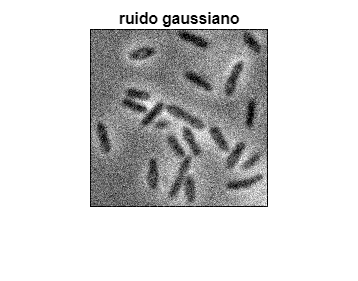

I=imread ('bacteria.tif');  
J=imnoise(I, 'gaussian' ,0,0.01); 
imshow(J),title('ruido gaussiano') 

g=fspecial('average',[5 5]) 

g =     0.0400    0.0400    0.0400    0.0400    0.0400
    0.0400    0.0400    0.0400    0.0400    0.0400
    0.0400    0.0400    0.0400    0.0400    0.0400
    0.0400    0.0400    0.0400    0.0400    0.0400
    0.0400    0.0400    0.0400    0.0400    0.0400


M1=filter2(g,J)/255; 
h=fspecial('unsharp') 

h =    -0.1667   -0.6667   -0.1667
   -0.6667    4.3333   -0.6667
   -0.1667   -0.6667   -0.1667


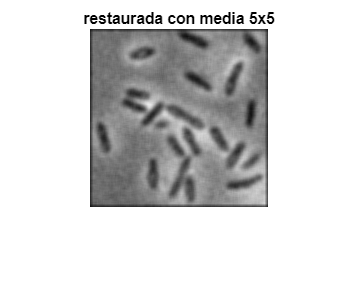

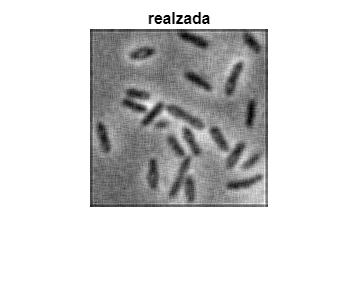

M2=abs(filter2(h,M1)); 
imshow(M1),title('restaurada con media 5x5'); figure, imshow(M2),title('realzada') 

c) Realza la imagen de la figura 26 utilizando un filtro lineal.

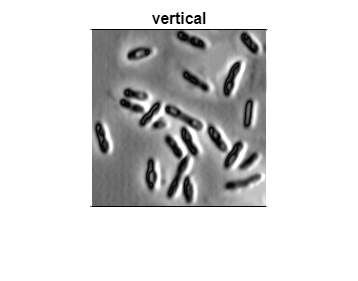

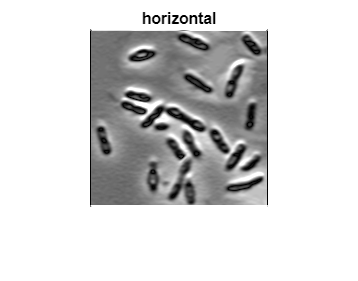

I=imread('bacteria.tif');  
gv=[-1 0 1;-1 1 1; -1 0 1]; 
gh=[1 1 1;0 1 0; -1 -1 -1]; 
Jv=abs(filter2(gv,I))/255; 
Jh=abs(filter2(gh,I))/255; 
imshow(Jv),title('vertical'); figure, imshow(Jh),title('horizontal')

d) Realza la imagen ecualizada de la espina dorsal (figura 22(a)) utilizando la imagen de bordes. 

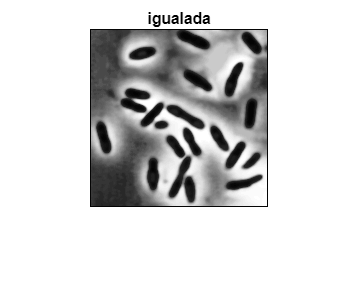

I=imread('bacteria.tif'); 
I=histeq(I); 
imshow(I),title('igualada') 

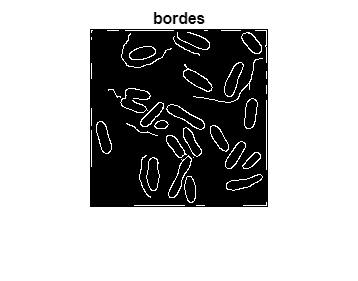

B=edge(I,'canny'); 
figure, imshow(B),title('bordes') 

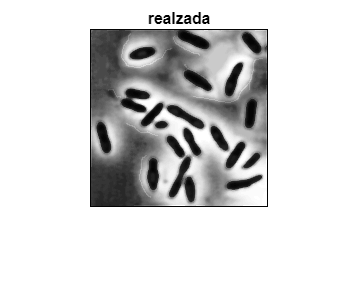

R=double(I)/255+0.1*double(B); 
figure, imshow(R),title('realzada')

e) Mejora la imagen de un insecto (figura 40) realzando sus bordes horizontales. 

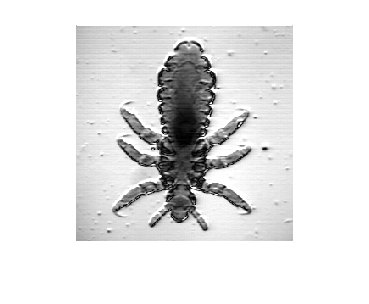

I = imread('BUG.TIF');
gh = [1 1 1; 0 1 0; -1 -1 -1]; 
Jh = abs(filter2(gh, I)) / 255;  
imshow(Jh);